# Lab 2: Biointerfacing with the Myo Armband - Doreen Ngo - Incomplete - DO NO DELETE!!!!!!!!

Look for sections of the lab requiring data to be recorded for the lab report, indicated by this icon:  

## Startup the Myo Armband Manager

- Launch the Myo Armband Manager. (Right-Click the tray icon and select “Armband Manager”)

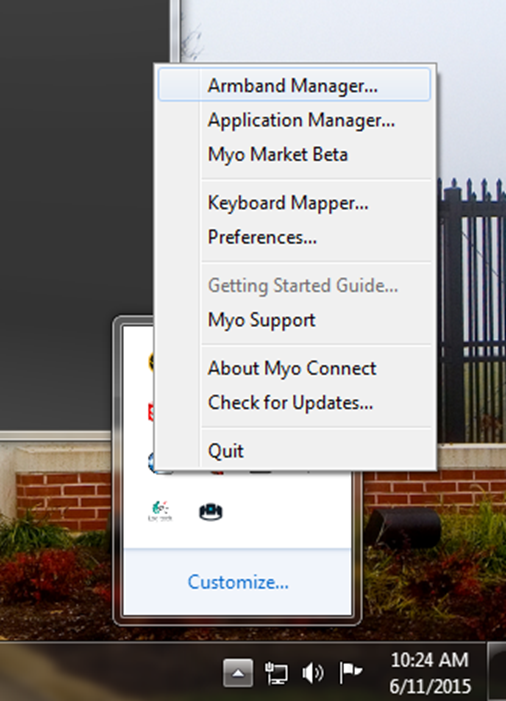        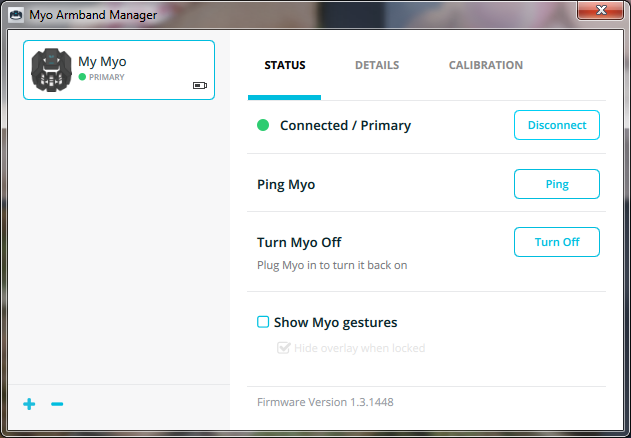

- Ensure the device is connected (Press the “Connect” button)

- Place the Myo on your arm with the logo parallel to the back of your hand

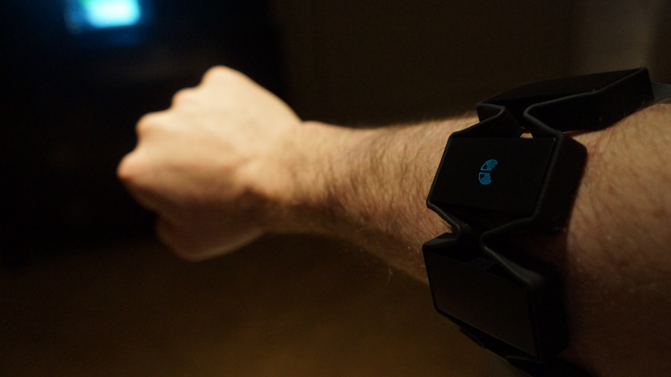

**Note: Myobands will go to sleep after 30 seconds of inactivity (indicated by the blue line LED going off). If you aren’t getting any signals when using the device, reactivate by shaking the armband.  The Myo armband attempts to correct this by periodically vibrating**

- Launch the MyoUdp.exe interface application from the +Inputs directory of the MiniVIE package (suggestion: pin this to your taskbar, you’ll likely use it a bit in this course).

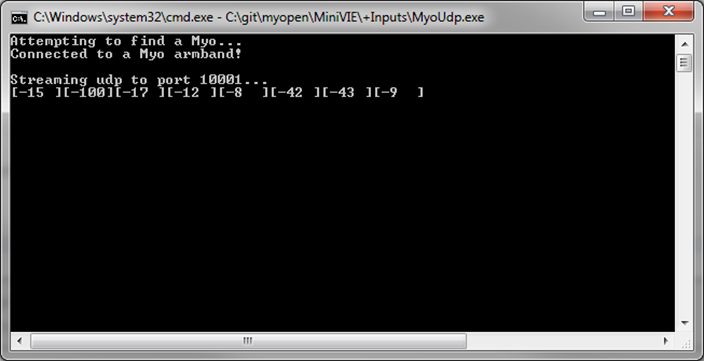

The numbers on the bottom row of this application should be changing.  If not, you're likely not streaming new data.  **Also, make sure you're only running one of these applications at a time!**

## Start the MiniVIE Myo Interface

Create the MATLAB Interface by creating a new script in the MATLAB editor, and enter the following commands.  Note: Upon issuing these commands the first time, this will launch a small executable that handles the device communication.

## Set up the MiniVIE path

cd('C:\GitHub\MiniVIE');
MiniVIE.configurePath;

[MiniVIE.m] Configured MiniVIE path at: C:\GitHub\minivie



%% Create an object for UDP interface to the Myo Armband
hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Calling constructor


hMyo.initialize();

[UserConfig.m] Calling constructor with config file C:\GitHub\minivie\user_config.xml
[UserConfig.m] myoUdpRate=200
[UserConfig.m] myoUdpPort1=10001
[UserConfig.m] myoUdpPort2=10002

Loaded pnet Version  2.0.5  2003-09-16 Copyright (C) Peter Rydesäter, Sweden, et al. , 1998 - 2003
[PnetClass] Opened pnet socket #0 at local port: 10001; Default destination: port 45001 @ 127.0.0.1
[PnetClass] Opened pnet socket #1 at local port: 10002; Default destination: port 45001 @ 127.0.0.1
[MyoUdp] UDP Data Stream 1-8 NOT Detected
[MyoUdp] UDP Data Stream 9-16 NOT Detected


cd('C:\GitHub\hrilabs\Lab2_EMGInterfacing');

## Plot some EMG Activity

Get some data and plot.  Note: You may have to run getData again if the first graph presents a flat line at zero due to the initialization sequence.

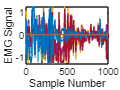

%% Get data and plot.  emgData size is [1000 samples x 8 channels]
emgData = hMyo.getData;
plot(emgData)
xlabel('Sample Number');
ylabel('EMG Signal')

**Example plot:**

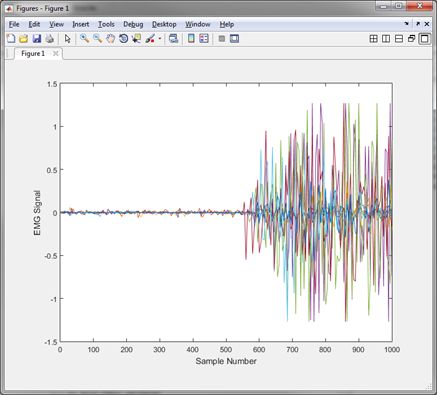

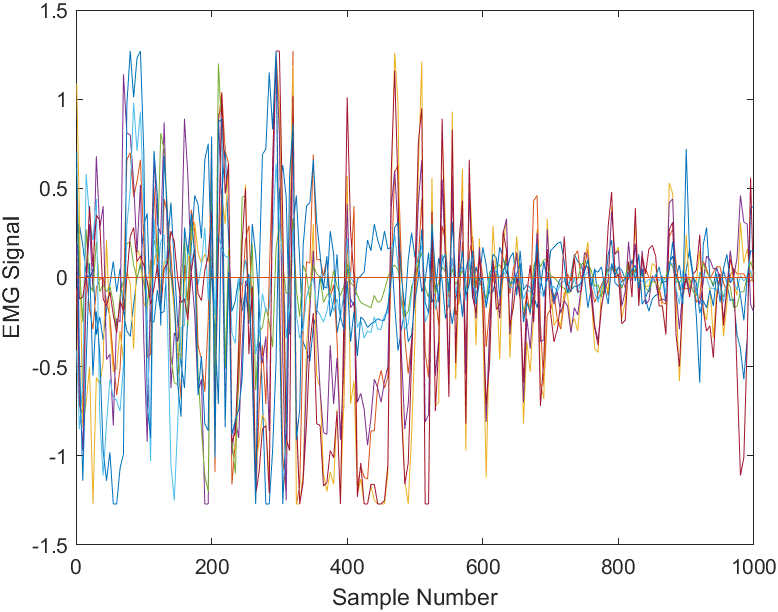

## View Streaming EMG

Open the real-time Signal Viewer.  Note: the Signal Viewer uses a MATLAB `timer`() object to automatically update the display.  While it is possible to run other commands, if performance is degraded, close the window when not in use.

[guiSignalViewer] Initializing...

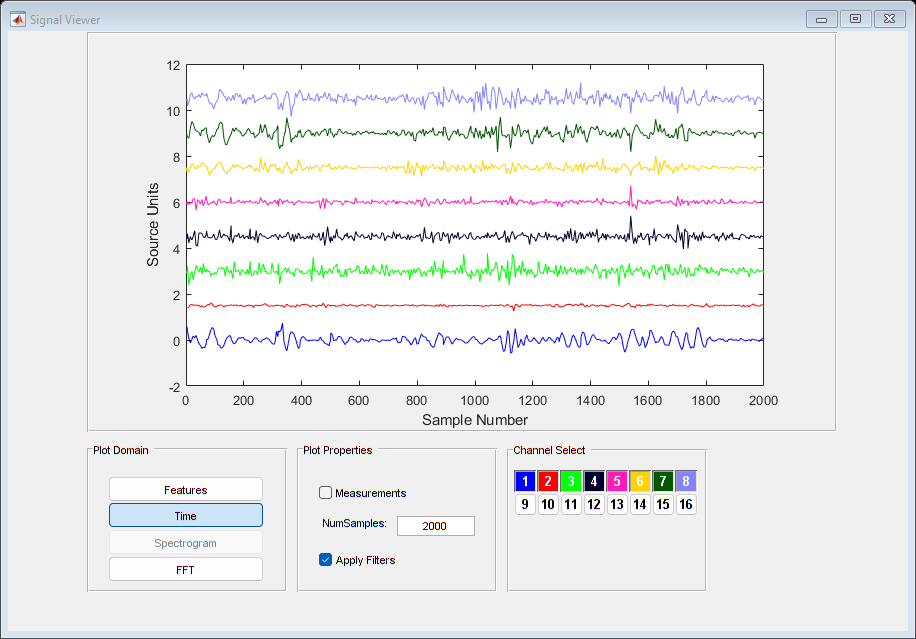

hViewer = GUIs.guiSignalViewer(hMyo);

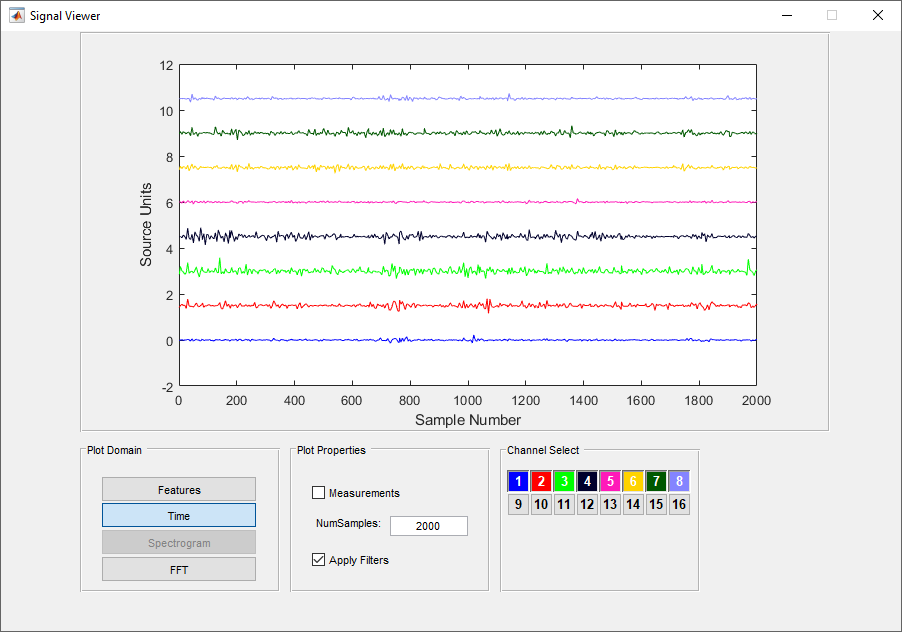

The first time you run this viewer, you will likely need to click on the numbers 1-8 in the channel select window to enable the Myo channel stream.

## Write Some Acquisition Code

 

Write a set of commands / function that will acquire a set of data (using the previous `hMyo.getData `command) and **save the result to a file describing the motion**.  The function buffers incoming data so the get data function represents the previous 1000 ms.  **Plot your results.**

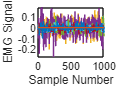

% Write your code to acquire data here

emgData1 = hMyo.getData;
emgData2 = hMyo.getData;
emgData3 = hMyo.getData;

% Write your code to save your results here

save('myEMGData_Doreen','emgData')

% Write your code to plot your results here

plot([emgData1, emgData2, emgData3])
xlabel('Sample Number');
ylabel('EMG Signal')

**Copy and paste plots generated by your code here:**

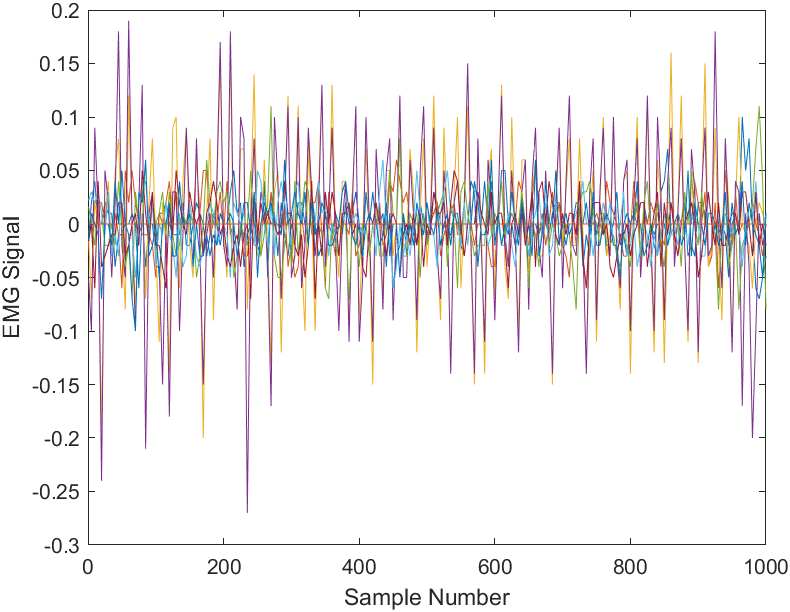

## Studying EMG Patterns

Compute the root mean square amplitude from channels during a few test movements.  Hint: Use the ‘Measurements’ checkbox to observe the Root Mean Square (RMS) and Peak to Peak (Pk-Pk) in the SignalViewer directly to confirm your measurements

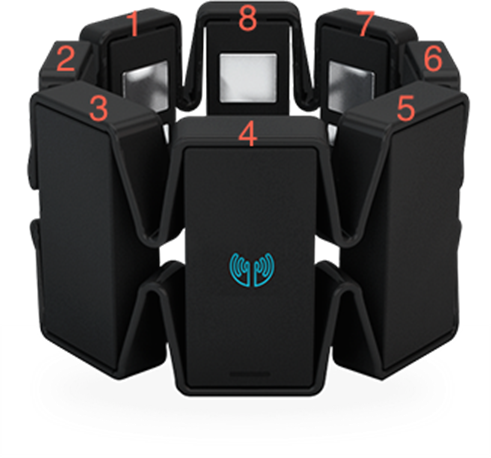

Record the RMS channel values for the 8 channels during the following movements. Please use the table given below.  (Note: For EMG, you must flex muscles as if working against resistance so that the muscle contraction is consistent and measurable.)

                                                                                    **Channel**

**                                                    %1        2         3        4       5        6        7         8**

**                                                    8        7         6        5       4        3        2         1   **

**% Note from Doreen: I accidental reversed the channels: so channels read from 8 to 1, left to right**

- Example movement:       2.2     0.0     3.3     1.0     0.7     0.5     0.8     1.0 

- Rest                            0.06        0.02     0.02    0.08      0.06      0.03     0.06    0.05     

- Wrist Flexion                0.2      0.1         0.05       0.10       0.12    0.27    0.14       0.13

- Wrist Extension             0.38      0.13       0.06      0.05     0.20     0.09     0.08     0.35    

- Wrist Pronation           0.2           0.24      0.09      0.14      0.27       0.17     0.07      0.21

- Wrist Supination           0.14        0.08      0.05      0.16      0.28     0.10      0.03     0.13    

- Cylindrical Grasp          0.21        0.25       0.11        0.09      0.4     0.05   0.04    0.15

- Tip Grasp                       0.10       0.12       0.03       0.02       0.06    0.07      0.07      0.11

- Lateral Grasp                 0.21        0.04        0.02       0.12         0.06    0.33      0.19     0.60      

- Index Finger                   0.05      0.04       0.08          0.19      0.10         0.09     0.1      0.52

- Middle Finger                0.12        0.05        0.04         0.4       0.5          0.09        0.18    0.8

- Ring Finger                     0.23    0.05          0.09          0.21       0.08          0.25      0.13     0.37

- Little Finger                    0.16       0.09         0.08        0.30      0.19       0.08           0.14        0.27

**Questions**:

- **Find 2 pairs of movements with very different EMG channel activity.  Do these movements make sense?**

- **Wrist Flexion and Wrist Extension from the above table have very different EMG activity. This makes sense as the flexion would send higher signal levels to channels 1 to 4, and extension would send higher signal levels to channels 5 to 8.**

- **Open Hand (Flat - "paper") and Close Hand (Fist - "rock"): When Open Hand (Flat), channel 5 reads the highest: 0.33 V RMS. When close hand (making a fist), channels 1 and 8 read the highest: 0.22 V RMS. This makes sense as electrode 5 is near my forearm which is the most active part of my forearm muscle when I open the hand flat. Electrodes 1 and 8 are in axis to my inner palm, which is the most active part of the muscle when I close my hand to make a fist, so this makes sense.**

- **Find 2 pairs of movements with very similar EMG channel activity.  Do these movements make sense?**

- **Wrist  radial deviation ("adduction") and wrist ulnar deviation ("abduction") have similar EMG activity for channels 3 to 8 while channels 1 and 2 have little response. This makes sense because I'm using the same outer forearm muscles to move angle my wrist in the same plane back and forth**

- **Extending index finger and extending middle finger: They have similar EMG activity for all channels except channels 3 and 6. This may make sense as they are adjacent fingers and I need to use the same forearm muscles to extend them. **

## Starting the MiniVIE Pattern Recognition Interface

[MiniVIE.m] Configured MiniVIE path at: C:\GitHub\minivie
[UserConfig.m] userFilePrefix=USER_


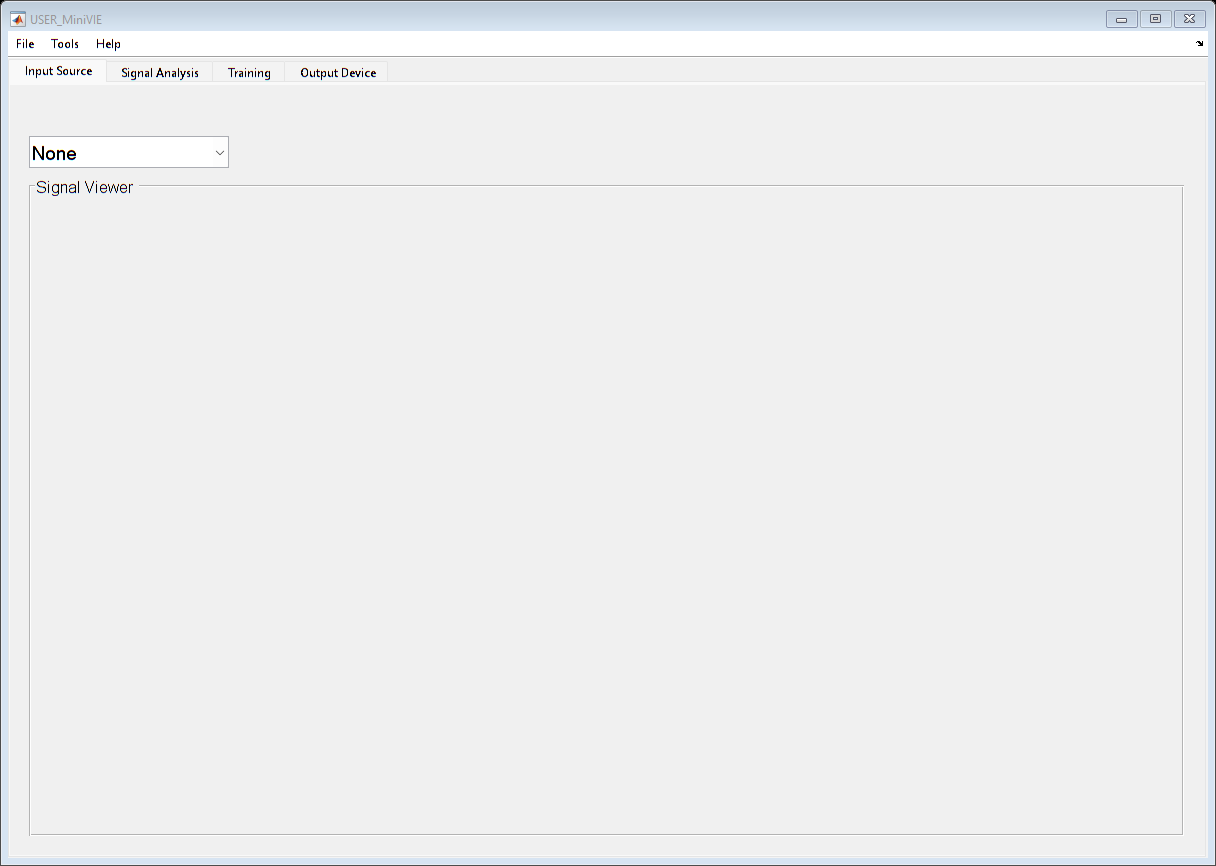

obj = MiniVIE;

If prompted for a configuration file, use the default “user_config.xml”

Set the drop-down menus within the MiniVIE window to those shown in the figure below. For Inputs, select “Thalmic Labs MyoUdp”.  For Signal Analysis, select “LDA Classifier”

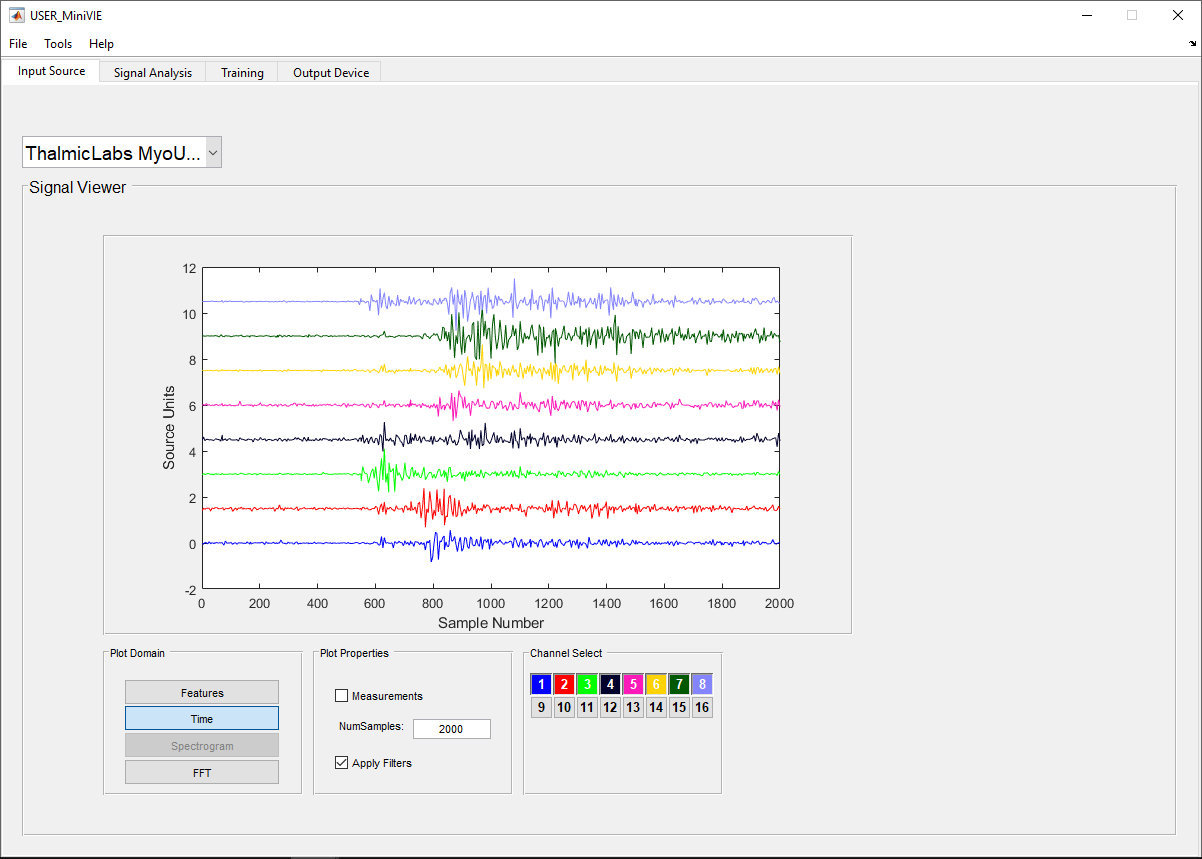

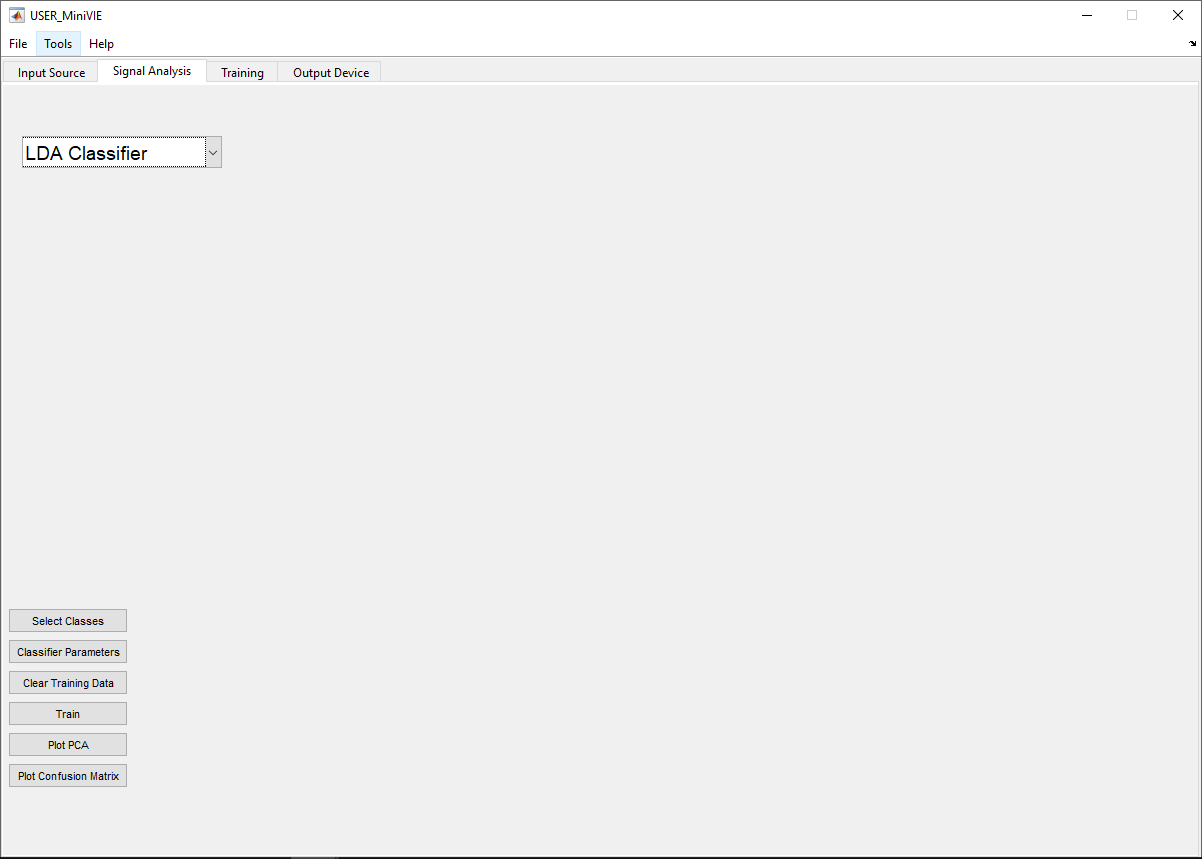

## Collect Training Data

Press the “Select Classes” button to bring up the window for selecting which limb motions to train or classify using the Myoband.  Use the motion classes that you collected EMG data for above.

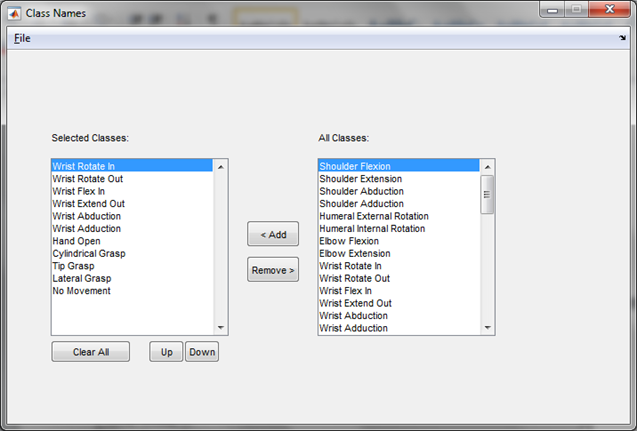

Select the Output Device: “MplUnity”

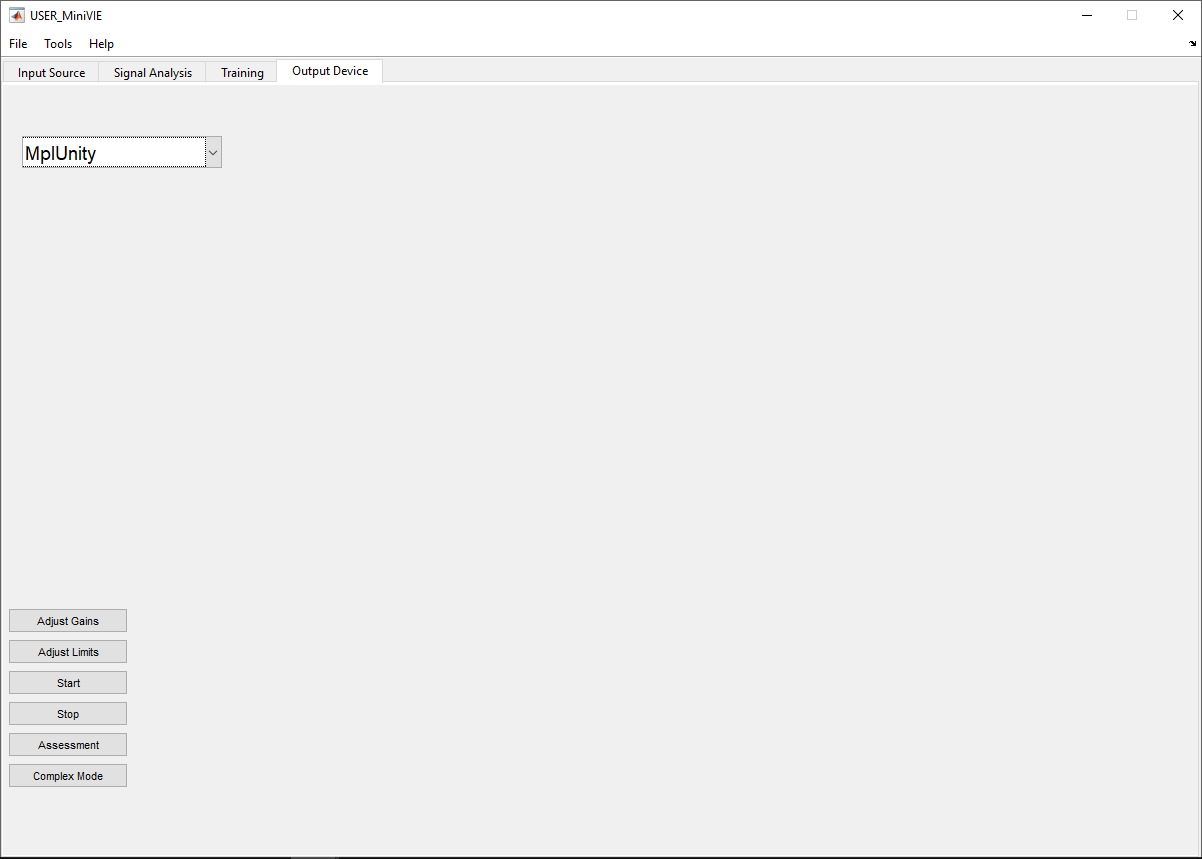

Add data to each of the classes by performing the motion and pressing the “Add” button (press it again to stop collecting).  After a few seconds of relaxing, repeat the process again to add more training data.

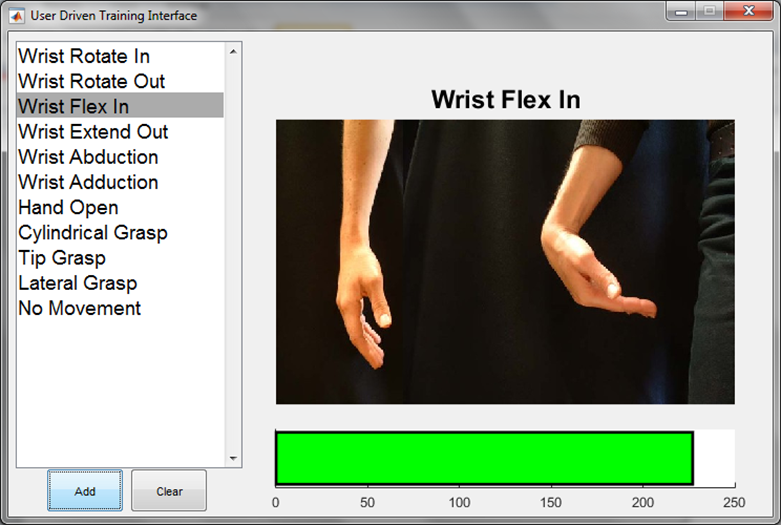

Save your data from the MiniVIE GUI.  File -> Save Training Data.  Save this file as Lab2_##_TrainingData.trainingData in the Lab2 folder under hrilabs/, where ## is your computer number.

## Visualize Your Training Data

Plot the confusion matrix for the movements performed by going to the Signal Analysis tab of the MiniVIE and clicking on Plot Confusion Matrix.  Write down any movements with low prediction accuracy.  Consider potential factors that contributed to error such as similarity of the movement, or improper training.

**Example Plot:**

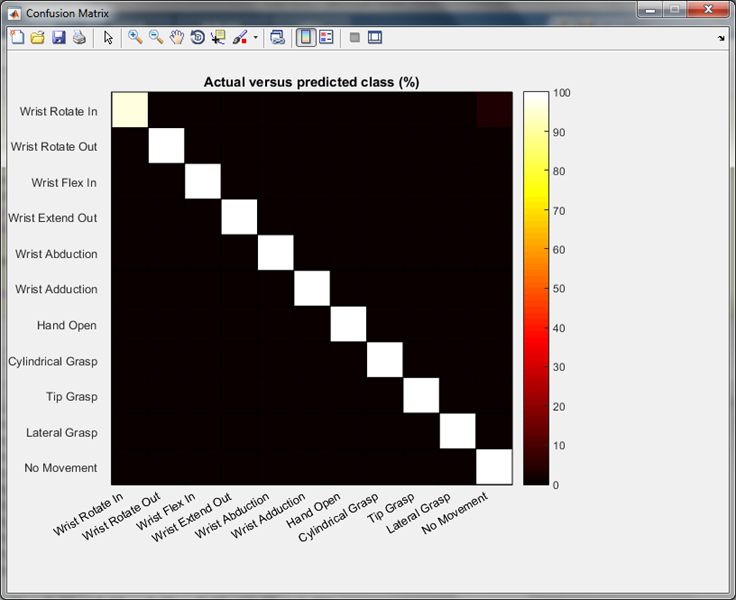

**Paste your plot here:**

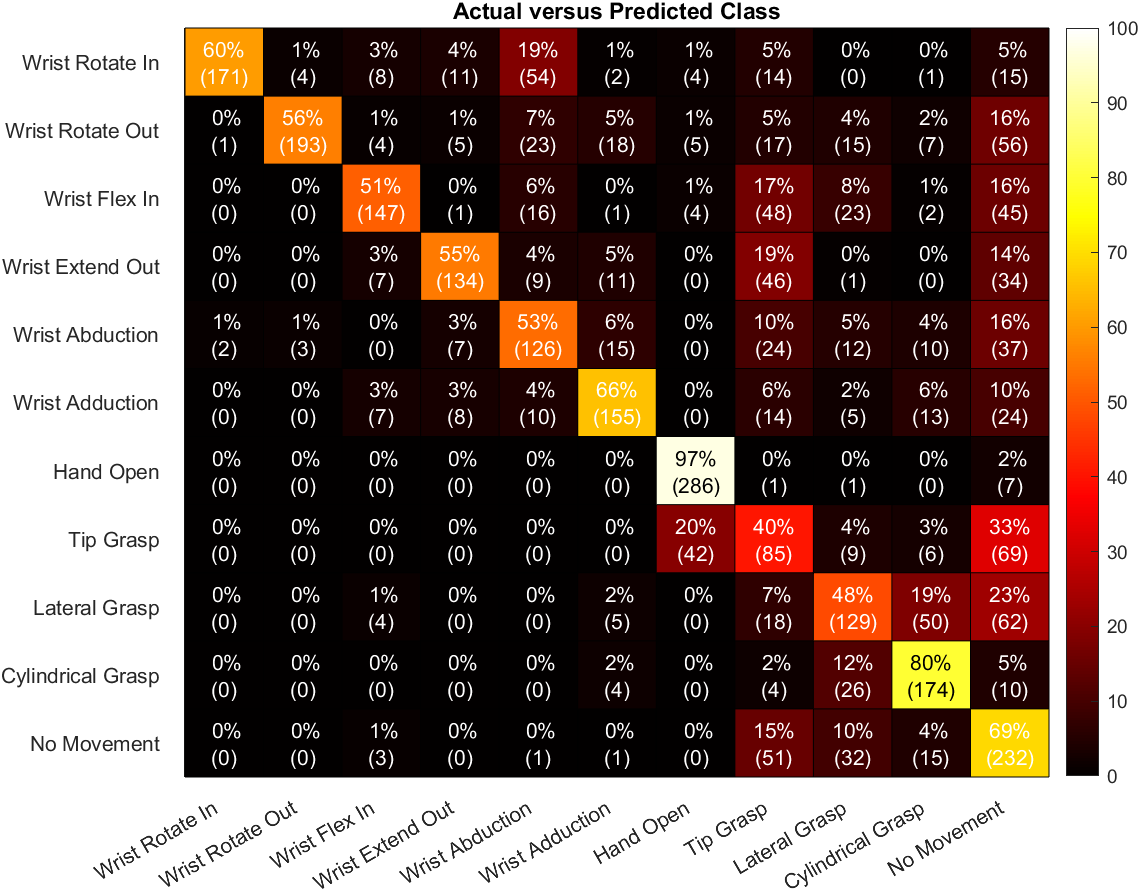

**Any low performing classes?**

In addition to the confusion matrix, you can also visualize the Principal Components of the EMG feature data to consider where data might overlap and lead to classification inaccuracies.  Go to the Signal Analysis tab of the MiniVIE and click on Plot PCA.

**Example Plot:**

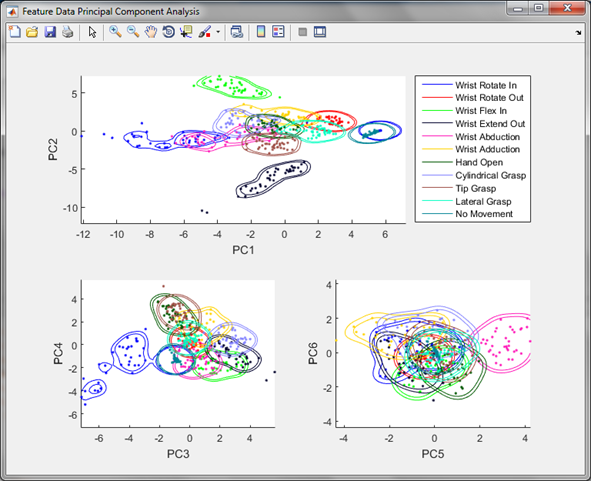

**Paste your plot here:**

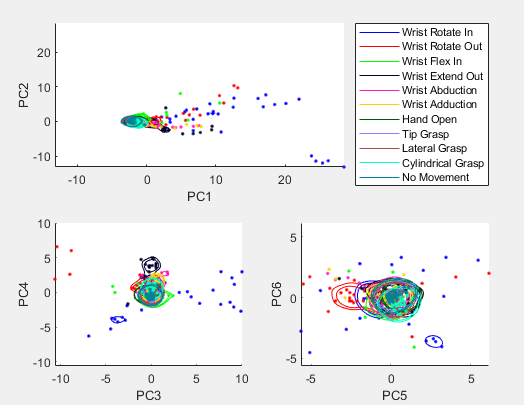

## **Submitting This Lab**

Export this *.mlx file as Lab2_##_<LastName1>_<LastName2>.pdf (## should be your computer number) and email to Lauren.Diaz@jhuapl.edu